# Energy Optimal Trajectory planning for quadrotor drone

Required: Optimization Toolbox, Symbolic Math Toolbox

clear; clc; close all;

## Configuration

fprintf('MATLAB version: %s\n', version);

MATLAB version: 26.1.0.3203278 (R2026a)


## UAV Dynamic model

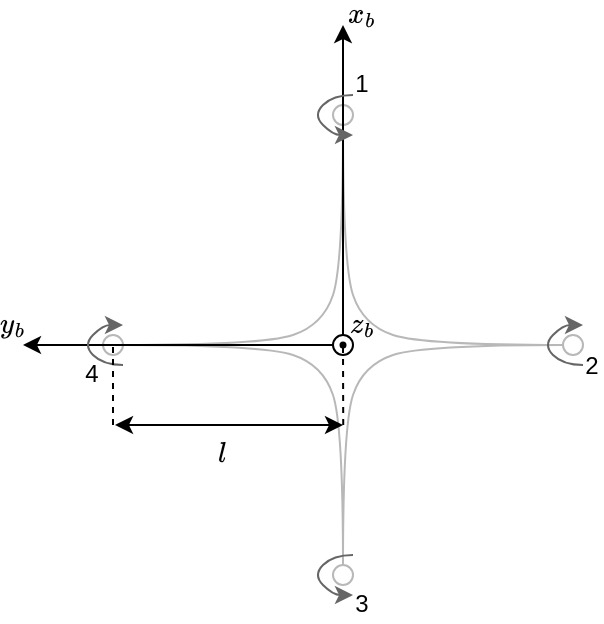

**Newton-Euler equations**

Let $\xi=[x\,y\,z]^T$ be the position of the centre of mass in $E_0$. The rigid-body dynamics are


$$\dot{\xi} = v$$



$$m\dot{v} = f$$



$$\dot{R_b} = R_b \hat{\bar{\Omega}}$$



$$I\dot{\bar{\Omega}} = - \bar{\Omega} \wedge I\bar{\Omega} + \Gamma$$


where $v\in E_0$ is the linear velocity, $f\in E_0$ the sum of the external forces (thrust and gravity), $\bar\omega\in E_b$ the angular velocity and $\Gamma\in E_b$ the total external torque. The first two equations are Newton's second law for the translation. The last two are the rotation kinematics and Euler's equation. The term $-\bar\omega\wedge I\bar\omega$ is the gyroscopic coupling of the rigid body.

**Forces and torques generated by the rotors**

Each rotor $i$ spins at $\omega_i$ and produces a thrust $k_T\omega_i^2$ along $z_b
$. The total thrust and the gravitational force are :

$T_{thr} = k_T \sum_{i=1}^4\omega_i^2, \qquad f_g = -mgE(3), \qquad E(3)=[0\,0\,1]^T $.

A thrust $k_T\omega_i^2$ applied at $(x_i,y_i,0)$ produces the torque $(y_i k_T\omega_i^2,\,-x_i k_T\omega_i^2)$ about $x_b$ and $y_b$. With the rotor positions, the torques generated by the rotors in $E_b$ are :


$$\Gamma(E_b) =
\left[\matrix{
l\,k_T(-\omega_2^2 + \omega_4^2) \cr
l\,k_T(-\omega_1^2 + \omega_3^2) \cr
k_Q(\omega_1^2 - \omega_2^2 + \omega_3^2 - \omega_4^2)
}\right]$$


where $l$ [m] is the distance from each rotor to the centre of mass, $k_T$ [$N/(rad/s)^2$] the thrust coefficient and $k_Q$ [$Nm/(rad/s)^2$] the reaction-torque coefficient.

**Scalar equations of motion**

The third column of $R_b$ gives the direction of the thrust in $E_0$:


$$\ddot{\xi} = \frac{1}{m} R_b \left[\matrix{0 \cr 0 \cr T_{thr}}\right] - \left[\matrix{0 \cr 0 \cr g}\right]$$



$$\ddot{x} = (c_\psi s_\theta c_\phi + s_\psi s_\phi)\frac{T_{Thr}}{m}$$



$$\ddot{y} = (s_\psi s_\theta c_\phi - c_\psi s_\phi)\frac{T_{Thr}}{m}$$



$$\ddot{z} = -g+(c_\theta c_\phi)\frac{T_{Thr}}{m}$$


Let $[p,q,r]^\top=\bar\omega$ be the body rates. The Euler-angle rates satisfy $\dot{\eta}=W(\eta)\,\bar\omega$ with $W = \left[\matrix{
1 & s_\phi t_\theta & c_\phi t_\theta \cr
0 & c_\phi & -s_\phi \cr
0 & s_\phi/ c_\theta & c_\phi/ c_\theta
}\right]$

**State model**

The model is nonlinear, time-invariant, continuous-time, MIMO (12 states, 4 inputs) and deterministic. The state and input are


$$X = \left[\matrix{x&y&z&v_x&v_y&v_z&\phi&\theta&\psi&p&q&r}\right]^\top\in\mathbb{R}^{12},
\qquad
\omega = \left[\matrix{\omega_1&\dots&\omega_4}\right] ^\top\in\mathbb{R}^{4},$$


and the full model under can be written as:


$$\dot{x} = v_x,$$



$$\dot{y} = v_y,$$



$$\dot{z} = v_z,$$



$$\dot{v}_x = \frac{k_T}{m} \left(\omega_1^2+\omega_2^2+\omega_3^2+\omega_4^2\right) \left(\cos\psi\sin\theta\cos\phi+\sin\psi\sin\phi\right),$$



$$\dot{v}_y = \frac{k_T}{m} \left(\omega_1^2+\omega_2^2+\omega_3^2+\omega_4^2\right) \left(\sin\psi\sin\theta\cos\phi-\cos\psi\sin\phi\right),$$



$$\dot{v}_z = \frac{k_T}{m} \left(\omega_1^2+\omega_2^2+\omega_3^2+\omega_4^2\right) \cos\theta\cos\phi-g,$$



$$\dot{\phi} = p+\sin\phi\tan\theta\,q+\cos\phi\tan\theta\,r,$$



$$\dot{\theta} = \cos\phi\,q-\sin\phi\,r,$$



$$\dot{\psi} = \frac{\sin\phi\,q+\cos\phi\,r}{\cos\theta},$$



$$\dot{p} = \frac{-(J_{zz}-J_{yy})qr+ l k_T(\omega_4^2-\omega_2^2)}{J_{xx}},$$



$$\dot{q} = \frac{-(J_{xx}-J_{zz})rp+ l k_T(\omega_3^2-\omega_1^2)}{J_{yy}},$$



$$\dot{r} = \frac{-(J_{yy}-J_{xx})pq+ k_Q(\omega_1^2-\omega_2^2+\omega_3^2-\omega_4^2)} {J_{zz}}.$$


function dX = dyn(X, w, drone)
% Rigid-body dynamics (12 states), rotor speeds w (4 x M) as input.
% Element-wise: works for a single column (simulation) and for M nodes at once (NLP,
% numeric / symbolic / optimization expressions).
    g = 9.81; % Acceleration of gravity

    vx = X(4,:);   vy = X(5,:);     vz = X(6,:);
    phi = X(7,:);  th = X(8,:);     psi = X(9,:);
    p = X(10,:);   q = X(11,:);     r = X(12,:);

    cphi = cos(phi);  sphi = sin(phi);
    cth  = cos(th);   sth  = sin(th);   tth = sth./cth;
    cpsi = cos(psi);  spsi = sin(psi);

    w2   = w.^2;
    T    = drone.k_T*(w2(1,:) + w2(2,:) + w2(3,:) + w2(4,:));      % total thrust
    Gphi = drone.l*drone.k_T*(w2(4,:) - w2(2,:));                  % torques
    Gth  = drone.l*drone.k_T*(w2(3,:) - w2(1,:));
    Gpsi = drone.k_Q*(w2(1,:) - w2(2,:) + w2(3,:) - w2(4,:));

    % Translation: (R*[0;0;T] - [0;0;m g])/m, third column of R
    ax = (cpsi.*sth.*cphi + spsi.*sphi).*T/drone.m;
    ay = (spsi.*sth.*cphi - cpsi.*sphi).*T/drone.m;
    az = (cth.*cphi).*T/drone.m - g;

    % Euler-angle kinematics: deta = W(eta)*[p;q;r]
    dphi = p + sphi.*tth.*q + cphi.*tth.*r;
    dth  = cphi.*q - sphi.*r;
    dpsi = (sphi.*q + cphi.*r)./cth;

    % Euler's equation (diagonal inertia): J*dom = -om x (J om) + G
    dp = (-(drone.Jzz - drone.Jyy).*q.*r + Gphi)/drone.Jxx;
    dq = (-(drone.Jxx - drone.Jzz).*r.*p + Gth )/drone.Jyy;
    dr = (-(drone.Jyy - drone.Jxx).*p.*q + Gpsi)/drone.Jzz;

    dX = [vx; vy; vz; ax; ay; az; dphi; dth; dpsi; dp; dq; dr];
end

## Battery

The first-order Thévenin model consists of an open-circuit voltage source $V_{oc}(\text{SoC})$ in series with an internal resistance $R_{\text{int}}$ and with a parallel branch $R_d\parallel C_d$ that represents the diffusion dynamics:

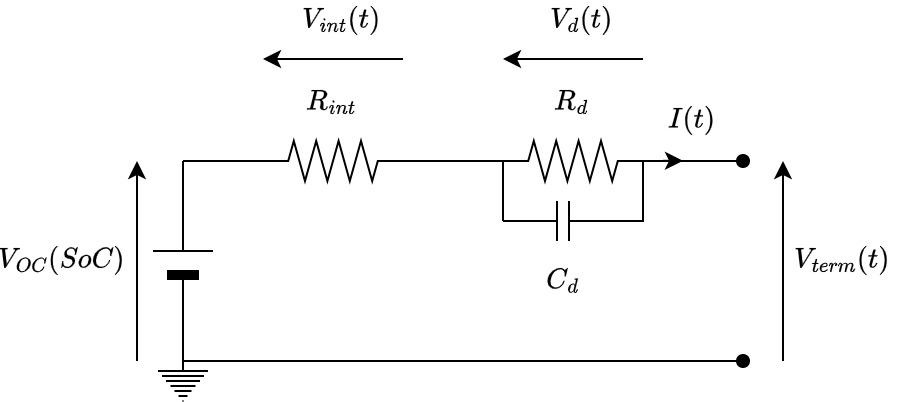

The branch $R_d\parallel C_d$ is neglected (i.e. $V_d(t)=0$), which removes the diffusion dynamics. The model then reduces to a purely resistive one, which is static (algebraic) and no longer of first order:


$$V_{oc}(\text{SoC}) = V_{\text{term}}(t) + R_{\text{int}} \, I(t)$$


The consequence is that the terminal voltage responds instantaneously to a change of current, whereas the full circuit would show a transient with time constant $R_dC_d$.

Also, the open-circuit voltage follows:


$$V_{oc}(SoC)=\sum_{i=0}^n\lambda_i SoC^i +log(SoC)SoC$$


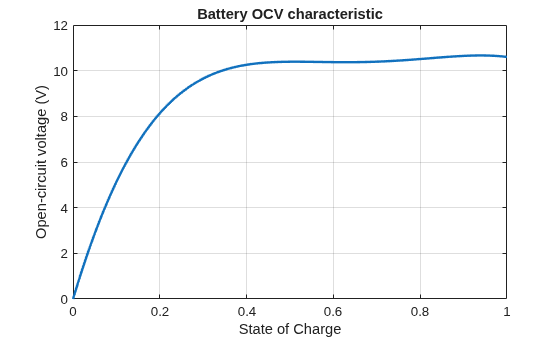

batt.Pol_ocv = [-55 153 -155 67.6 0];
soc_grid = linspace(0, 1, 200);

V_oc_grid = polyval(batt.Pol_ocv, soc_grid);

positive = soc_grid > 0;
V_oc_grid(positive) = V_oc_grid(positive) + ...
    soc_grid(positive).*log(soc_grid(positive));

figure;
plot(soc_grid, V_oc_grid, 'LineWidth', 1.8);
grid on;
xlabel('State of Charge');
ylabel('Open-circuit voltage (V)');
title('Battery OCV characteristic');

**State-of-Charge**


$$\dot{\text{SoC}}(t) = -\frac{I(t)}{C_{\text{batt}}}$$


where $C_{\text{batt}}$ is the battery capacity in ampere-seconds $[A\,s]$ (a capacity of $x$ mAh corresponds to $3.6\,x$ $A\,s$). The equation is dimensionally consistent: $[\mathrm{A}]/[\mathrm{A\,s}]=[\mathrm{s^{-1}}]$. It is a pure Coulomb counting, i.e. it assumes a unit coulombic efficiency and a capacity independent of the discharge rate (no Peukert effect). The SoC is dimensionless, with $\text{SoC}\in[0,1]$.

Also, $I(t) = \sum_{k=1}^4I_{BLDCM,k}$. 

## BLDCM Model

Each rotor is driven by a brushless DC motor modeled as an equivalent DC machine.

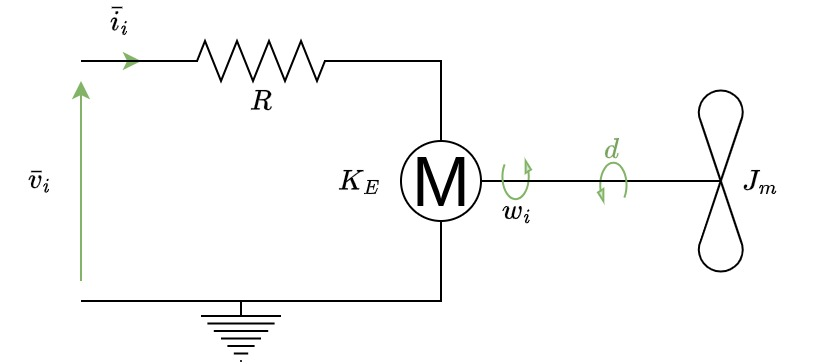

The electrical and mechanical equations are


$$L\dot{\bar{i}}_i = \bar{v}_i - R\bar{i}_i - K_E\omega_i$$



$$J_r\,\dot{\omega}_i = K_E\bar{i}_i - d\,\omega_i^2 - D_f\,\omega_i - T_f\,\mathrm{sign}(\omega_i)$$


where $V_i$ is the applied voltage, $I_i$ the current, $R$ and $L$ the winding resistance and inductance, $K_E$ the back-EMF constant, $J_r$ the rotor inertia, $d$ the propeller load coefficient, $D_f$ the viscous friction coefficient and $T_f$ the dry friction torque.

The four terms of the mechanical equation are:

1. **Electromagnetic torque **$\tau_{em}=K_EI_i$. The back-EMF is $K_E\omega_i$, and the current is $I_i=(V_i-K_E\omega_i)/R$ when the electrical dynamics are neglected.

2. **Propeller load** $\tau_{prop}=d\,\omega_i^2$, with $d=k_Q
$. It is the aerodynamic reaction torque of the propeller, quadratic in the speed. It couples the motor to the airframe dynamics and appears in $\Gamma_\psi$.

3. **Viscous friction** $\tau_{visc}=D_f\,\omega_i$, representing bearing losses and viscous drag of the rotor.

4. **Dry friction** $\tau_{dry}=T_f\,\mathrm{sgn}(\omega_i)$.

**Assumption.**

**(M1)** $D_f=T_f=0$.

**(M2)** (quasi-static current) $L\dot I_i\simeq0$. This singular-perturbation reduction is valid when $L/R\ll\tau_m$, where $\tau_m$ is the mechanical time constant defined below.

Finally the BLDCM equation can be written as:


$$\dot{\omega_i} = \frac{1}{J_r}(K_E\,\bar{i}_i-k_Q\, \omega_i^2)$$


`with`


$$\bar{i}_i = \frac{V_{term} \cdot D_{C,i}-K_E\,\omega_i}{R}$$


**Note on the BLDCM-Battery algebraic loop**

Looking back at the equations, we can identify an algebraic loop.

$V_{term}$ is required to compute $i_k$, but in the battery, (all 4) $i_k$ are needed to compute $V_{term}$.

Building the model as is in simulink triggers an algebraic loop warning. This issue can be also spotted when writting the model as a matlab functions, since the two variables need each others.

Let us handle the issue.

For each motor $k$, we have :


$$i_k=\frac{V_{term}D_{c,k}-K_E\omega_k}{R}$$


The output voltage is :


$$V_{term}=V_{oc}-R_{int} (\sum_{k=1}^{4}D_{c,k}i_k)$$


Replacing each $i_k$ in the sum and developping gives :


$$\sum_{k=1}^{4}D_{c,k}i_k=\frac{1}{R} \Big[ V_{term}\sum_{k=1}^{4}D_{c,k}^2 -K_E\sum_{k=1}^{4}D_{c,k}\omega_k \Big]$$


Let


$$A=\sum_{k=1}^{4}D_{c,k}^2$$



$$B=K_E\sum_{k=1}^{4}D_{c,k}\omega_k$$


We get:


$$V_{term} = V_{oc}-\frac{R_{int}}{R}(AV_{term} - B)$$


Then :


$$V_{term}\Big(1 + \frac{R_{int}A}{R}\Big) = V_{oc} + \frac{R_{int}B}{R}$$


Finally :


$$V_{term} = \frac{R\,V_{oc}+R_{int}\,B}{R + R_{int}\,A}$$


And each current :


$$i_k=\frac{V_{term}D_{c,k}-K_E\omega_k} {R}$$


function [I_batt, dw] = dyn_bldcm(Dc, V_oc, w, batt, mot)
% BLDC motors + battery. The algebraic loop (V_term <-> motor currents) is solved in closed form;
% quasi-static current (L di/dt = 0). Dc, w: 4x1.
    A = sum(Dc.^2);
    B = mot.KE*sum(Dc.*w);
    V_term = (mot.R*V_oc + batt.R_int*B)/(mot.R + batt.R_int*A);   % battery terminal voltage
    i_m    = (V_term*Dc - mot.KE*w)/mot.R;                         % motor currents
    I_batt = sum(Dc.*i_m);                                         % battery current
    dw     = (mot.KE*i_m - mot.d*w.^2)/mot.Jr;                     % rotor accelerations
end

### Feedforward + PI controller

The ESC of the BLCM controls the voltage using Pulse-Width Modulation. The voltage and current are generated as follows:


$$\bar{v}_i = V_{term} \cdot D_{C,i}$$



$$I_{BLDCM,i} = \bar{i}_i \cdot D_{C,i}$$


Where $V_{term}$ Is the voltage output of the battery, and $I_{BLDCM,i}$ is the current of the $i^{th}$ motor.

The duty-cycle can be determined through experimental correlations, however, we chose to make a feedforward function $D_{c,i}=f(\omega_{i,ref})$ using the electrical and mechanical equations in steady state.

Assuming $V_{term} \simeq E_{ocv}$, we can show: $D_{c,k} = \frac{K_E\omega_k+ R\frac{k_Q}{K_E}\omega_k^2} {E_{ocv}}$.

This feedforward controller is supplemented by a PI controller, adding 4 more states.

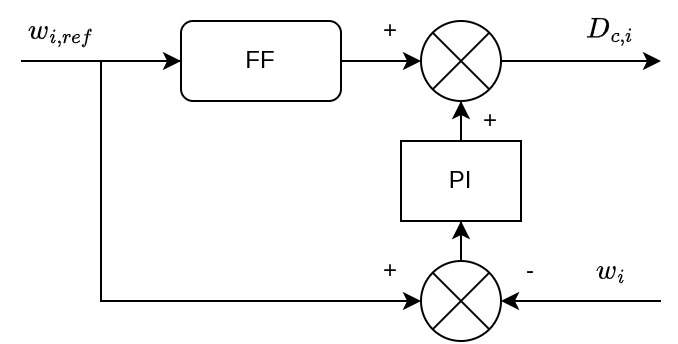

The PI coefficients were chosen by linearizing the BLDCM model (electrical and mechanical equations) around $(D_{c,i},w_i)=(0,0)$.

function [Dc, dz] = dutycycle(w_ref, w, z, batt, mot)
% Feedforward (steady-state motor equations) + PI feedback. Inputs 4x1.
% Dc: duty cycle in [0,1];  dz: derivative of the PI integrator state.
    e   = w_ref - w;
    Dff = (mot.R*mot.d)/(mot.KE*batt.E_ocv)*w_ref.^2 + mot.KE/batt.E_ocv*w_ref;
    Dc  = min(1, max(Dff + mot.Kp*e + mot.Ki*z, 0));
    dz  = e;
end

## Complete model

The complete model can be represented as:

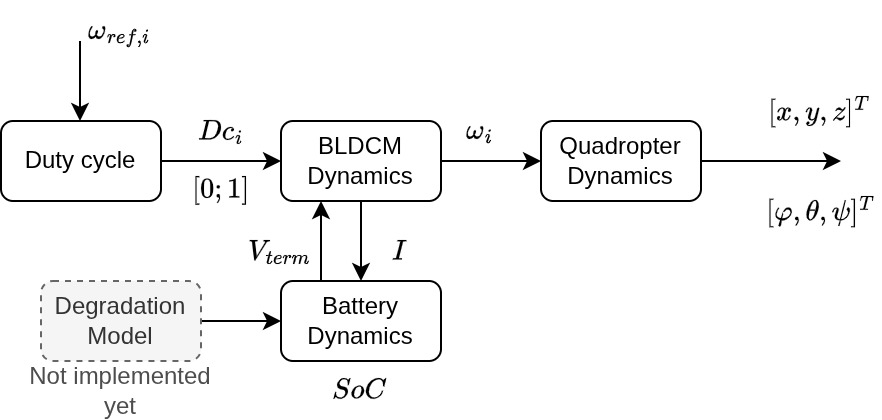

function dX = dyn_uav(X, w_ref, drone, batt, mot)
% Complete model (21 states), input: reference rotor speeds w_ref (4x1).
%   X = [x y z vx vy vz phi theta psi p q r (1:12) | w1..w4 (13:16) | SoC (17) | z1..z4 PI (18:21)]
    [Dc, dz]     = dutycycle(w_ref, X(13:16), X(18:21), batt, mot);
    V_oc         = polyval(batt.Pol_ocv, X(17)) + log(X(17))*X(17);
    [I_batt, dw] = dyn_bldcm(Dc, V_oc, X(13:16), batt, mot);
    dX = [dyn(X(1:12), X(13:16), drone); dw; -I_batt/batt.C; dz];
end

## UAV parameters

% UAV
drone.m   = 0.5;         % mass [kg]
drone.k_T = 3.0e-5;      % thrust coefficient [N/(rad/s)^2]
drone.k_Q = 7.5e-7;      % reaction-torque coefficient [N.m/(rad/s)^2]
drone.l   = 0.25;        % arm length [m]
drone.Jxx = 5.0e-3;      % inertia [kg.m^2]
drone.Jyy = 5.0e-3;
drone.Jzz = 9.0e-3;
drone.w_h = sqrt(drone.m*9.81/(4*drone.k_T));   % hover rotor speed [rad/s]

% Battery
batt.C       = 1.3*3600/10;            % capacity: 1300 mAh = 4680 A.s divided by 10 so that 
batt.Pol_ocv = [-55 153 -155 67.6 0];  % polynomial part of V_oc(SoC) (see dyn_uav)
batt.E_ocv   = 10.6; %11.1;                   % nominal open-circuit voltage, 3S LiPo [V]
batt.R_int   = 0.05;                   % internal resistance [Ohm]

% BLDCM
mot.R  = 0.1;            % winding resistance [Ohm]
mot.KE = 0.01;           % back-EMF constant [V.s/rad]
mot.Jr = 3.0e-5;         % rotor inertia [kg.m^2]
mot.d  = drone.k_Q;      % propeller load coefficient
mot.Kp = 9.4e-4;         % PI gains
mot.Ki = 9.42e-2;

## Scene parameters

scen.start_pos  = [0 0 0];     % [m]
scen.target_pos = [50 50 0];   % [m]
scen.start_vel  = [0 0 0];     % [m/s]
scen.target_vel = [0 0 0];     % [m/s] soft landing

Buildings (obstacles AABB):

% Buildings, one row each: [xc yc dx dy hz]
%   (xc,yc): centre at ground level; dx, dy: half horizontal sizes; hz: height -> z in [0, hz]
scen.buildings = [
    10, 10, 3, 4, 12;   % B1 thin and high
    30, 15, 5, 3,  7;   % B2 large
    27, 40, 4, 4, 15;   % B3 square, high
    35, 25, 3, 6,  9;   % B4 thin along y
    10, 25, 5, 5, 11;   % B5 square, high
    23, 23, 4, 4,  7    % B6 in the middle, small
    ];
scen.n_buildings = size(scen.buildings, 1);
scen.ecart = 1.0;                                  % safety distance to buildings [m]

Fly-space boundaries:

scen.x_min = 0;  scen.x_max = 55;                  % flight volume [m]
scen.y_min = 0;  scen.y_max = 55;
scen.z_min = 0;  scen.z_max = 30;

Display the scene:

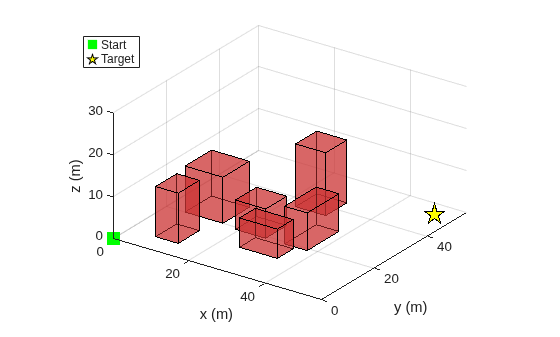

function draw_scene(scen)
% 3D scene: buildings, start and target (new figure, left open for further plotting).
figure; hold on; grid on; axis equal; view(35,25);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
Vc = [-1 -1 0; 1 -1 0; 1 1 0; -1 1 0; -1 -1 1; 1 -1 1; 1 1 1; -1 1 1];   % unit box
Fc = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];
for b = 1:scen.n_buildings
    bd = scen.buildings(b,:);                                             % [xc yc dx dy hz]
    patch('Vertices', Vc.*[bd(3) bd(4) bd(5)] + [bd(1) bd(2) 0], 'Faces', Fc, ...
        'FaceColor',[0.8 0.2 0.2], 'FaceAlpha',0.5, 'EdgeColor','k', 'HandleVisibility','off');
end
xlim([scen.x_min scen.x_max]);  ylim([scen.y_min scen.y_max]);  zlim([scen.z_min scen.z_max]);
plot3(scen.start_pos(1),  scen.start_pos(2),  scen.start_pos(3),  'gs', 'MarkerSize',12, ...
    'MarkerFaceColor','g', 'DisplayName','Start');
plot3(scen.target_pos(1), scen.target_pos(2), scen.target_pos(3), 'p',  'MarkerSize',16, ...
    'MarkerFaceColor','y', 'MarkerEdgeColor','k', 'DisplayName','Target');
end

draw_scene(scen); legend('Location','northwest');

## NLP solving with fmincon

The optimization problem is solved using MATLAB `fmincon` with the interior-point algorithm. At each iteration, the algorithm solves a quadratic approximation of the constrained optimization problem using first- and second-order derivative information. In particular, the second-order information is provided by the Hessian of the Lagrangian.

The optimization problem uses a state vector containing 16 variables:


$$X(t)=
\left[\matrix{
x & y & z &
v_x & v_y & v_z &
\phi & \theta & \psi &
p & q & r &
\omega_1 & \omega_2 & \omega_3 & \omega_4}\right]^{T}$$


These states describe the position, velocity, orientation, angular velocity and rotor speeds of the quadrotor. The control vector contains the time derivatives of the rotor angular velocities: $U(t)= \left[\matrix{
\dot{\omega}_1 &
\dot{\omega}_2 &
\dot{\omega}_3 &
\dot{\omega}_4}\right]^{T}$. Thus, the optimization directly controls the acceleration of each rotor, while the rotor angular velocities are included in the state vector. The battery state of charge and the PI controller integrator states are not included in the NLP. They are considered only in the subsequent full-model simulation.

**Parameters**

Tf_init = 10;  Tf_min = 2;  Tf_max = 40;   % final time [s]
N       = 60;                              % collocation intervals
nx = 16;  nu = 4;
w_h     = drone.w_h;
dw_max  = 500;                             % rotor acceleration bound [rad/s^2]
ang_lim = deg2rad(35);                     % bound on phi and theta [rad]
c_T     = 1;                               % weight of the final time in the cost [-]
p_sq    = 4;                               % super-ellipsoid exponent (even; larger = boxier but worse conditioning)

p0 = scen.start_pos(:);   pf = scen.target_pos(:);
bld_c = scen.buildings(:,1:2);                 % centres (xc, yc)
bld_a = scen.buildings(:,3:5) + scen.ecart;    % semi-axes with safety margin (ax, ay, az)
P_ref = Pm_rows(w_h*ones(4,1), zeros(4,1), drone, mot);   % hover power [W], normalises the cost

%assert(norm(dyn_vec([zeros(12,1); w_h*ones(4,1)], zeros(4,1), drone)) < 1e-9, 'Hover is not an equilibrium');

**Decision variables**

x_lb = [scen.x_min; scen.y_min; scen.z_min; -inf(3,1); -ang_lim; -ang_lim; -inf; -inf(3,1); 0.1*w_h*ones(4,1)];
x_ub = [scen.x_max; scen.y_max; scen.z_max;  inf(3,1);  ang_lim;  ang_lim;  inf;  inf(3,1); 1.8*w_h*ones(4,1)];

Tf = optimvar('Tf', 1,       'LowerBound', Tf_min,             'UpperBound', Tf_max);
X  = optimvar('X',  nx, N+1, 'LowerBound', repmat(x_lb,1,N+1), 'UpperBound', repmat(x_ub,1,N+1));
U  = optimvar('U',  nu, N+1, 'LowerBound', -dw_max,            'UpperBound', dw_max);

### Objective function

The first option requires writing the criterion as a function of $\omega_i$. The BLDCM electrical equation gives:


$$P_m=V_{term}I_{batt} = \sum_{k=1}^4V_{term}D_{c,k}i_k=\sum_{k=1}^4(R\,i_k^2 + K_E\omega_k i_k)$$


Then using the BLDCM mechanical equation :


$$P_m=\sum_{k=1}^4(\frac{R}{K_E^2}(J_r\dot{\omega}_k+k_Q\omega_k^2)^2 + \omega_k(J_r\dot{\omega}_k+k_Q\omega_k^2))$$


Then :


$$P_m=\sum_{k=1}^4\Big(k_Q\,\omega_k^3+\frac{Rk_Q^2}{K_E^2}\omega_k^4+J_r\dot{\omega}_k\omega_k+\frac{2RJ_rk_Q}{K_E^2}\omega_k^2\dot{\omega}_k + \frac{RJ_r^2}{K_E^2}\dot{\omega}_k^2\Big)$$


But this equation is the power drawn by the motors, assuming no internal resistance of the battery.

From the battery electrical equation:


$$R_{int}\,I_{batt}^2-V_{oc}\,I_{batt}+P_m=0$$


Taking the low-current root (The physical one, $I_{batt}\rightarrow P_m/V_{oc}$ as $R_{int}\rightarrow 0$) :


$$I_{batt}=\frac{V_{oc}-\sqrt{V_{oc}^2-4R_{int}P_m(\omega,\dot{\omega})}}{2R_{int}}$$


Since $4R_{inr}P_m/V_{oc}^2  \ll 1$:


$$V_{oc}I_{batt}=P_m+\frac{R_{int}}{V_{oc}^2}P_m^2+O(R_{int}^2)$$


At zeroth order $J\simeq\int P_m\,dt$. The $\omega\dot{\omega}$ and $\omega^2\dot{\omega}$ terms are exact derivatives and cancel out if $\omega(0) = \omega(t_f)$.

$\int_0^{t_f}\sum_k\Big(J_r\omega_k\dot\omega_k+\frac{2RJ_rk_Q}{K_E^2}\omega_k^2\dot\omega_k\Big)dt=\sum_k\Big[\frac{J_r}{2}\omega_k^2+\frac{2RJ_rk_Q}{3K_E^2}\omega_k^3\Big]_0^{t_f}$.

For this project, we will be using

$min\,J=\int_0^{tf}\sum_{k=1}^4\Big(k_Q\,\omega_k^3 + \frac{Rk_Q^2}{K_E^2}\omega_k^4 + \frac{RJ_r^2}{K_E^2}\dot{\omega}_k^2\Big)\,dt$.

The objective minimizes the electrical energy consumed by the four motors. In the implementation, the power is evaluated at the beginning, midpoint and end of each time interval, using Simpson's integration rule. The discrete criterion implemented in the code is:


$$J(X,U,T_f)=
\frac{T_f}{6N P_{ref}}
\sum_{k=1}^{N}
\left[
P_k+4P_{k+\frac{1}{2}}+P_{k+1}
\right]
}$$


Where :


$$P_k = P(\omega_k,U_k),\\
P_{k+\frac{1}{2}} = P\left(\frac{\omega_k+\omega_{k+1}}{2},\frac{U_k+U_{k+1}}{2}\right),\\
P_{k+1}= P(\omega_{k+1},U_{k+1}).$$


function P = Pm_rows(W, dW, drone, mot)
% Electrical motor power [W] at each node, summed over the 4 rotors. W, dW: 4 x M -> P: 1 x M.
a  = mot.Jr*dW + drone.k_Q*W.^2;
Pr = (mot.R/mot.KE^2)*a.^2 + W.*a;
P  = Pr(1,:) + Pr(2,:) + Pr(3,:) + Pr(4,:);
end

function J = elec_energy(W, dW, h, drone, mot)
% Electrical energy [J]: Simpson rule on each interval of length h. W, dW: 4 x (n+1) (n intervals).
n  = size(W,2) - 1;
Wa = W(:,1:n);    Wb = W(:,2:n+1);    dWa = dW(:,1:n);    dWb = dW(:,2:n+1);
P  = Pm_rows(Wa, dWa, drone, mot) + 4*Pm_rows((Wa+Wb)/2, (dWa+dWb)/2, drone, mot) + Pm_rows(Wb, dWb, drone, mot);
J  = h/6*sum(P);
end

h    = Tf/N;                                         % collocation step
prob = optimproblem('Objective', elec_energy(X(13:16,:), U, h, drone, mot)/P_ref + c_T*Tf);

### Constraints

The dynamics function serves as an equality constraint for the model states, using a trapezoidal collocation:


$$X_{k+1} - X_k - (\frac{h}{2})(f_k + f_{k+1}) = 0,\quad h = \frac{Tf}{N}$$


Assuming the trajectory will be "smooth", meaning variations of $(\omega_{ref,i})_{i\in [1;4]}$variations will stay  below the cut-off frequency (around $100\,rad/s$according to the figures below), we can reduce the number of variables by using only the 6-DoF mechanical model, neglecting the motor dynamics, and the battery model.

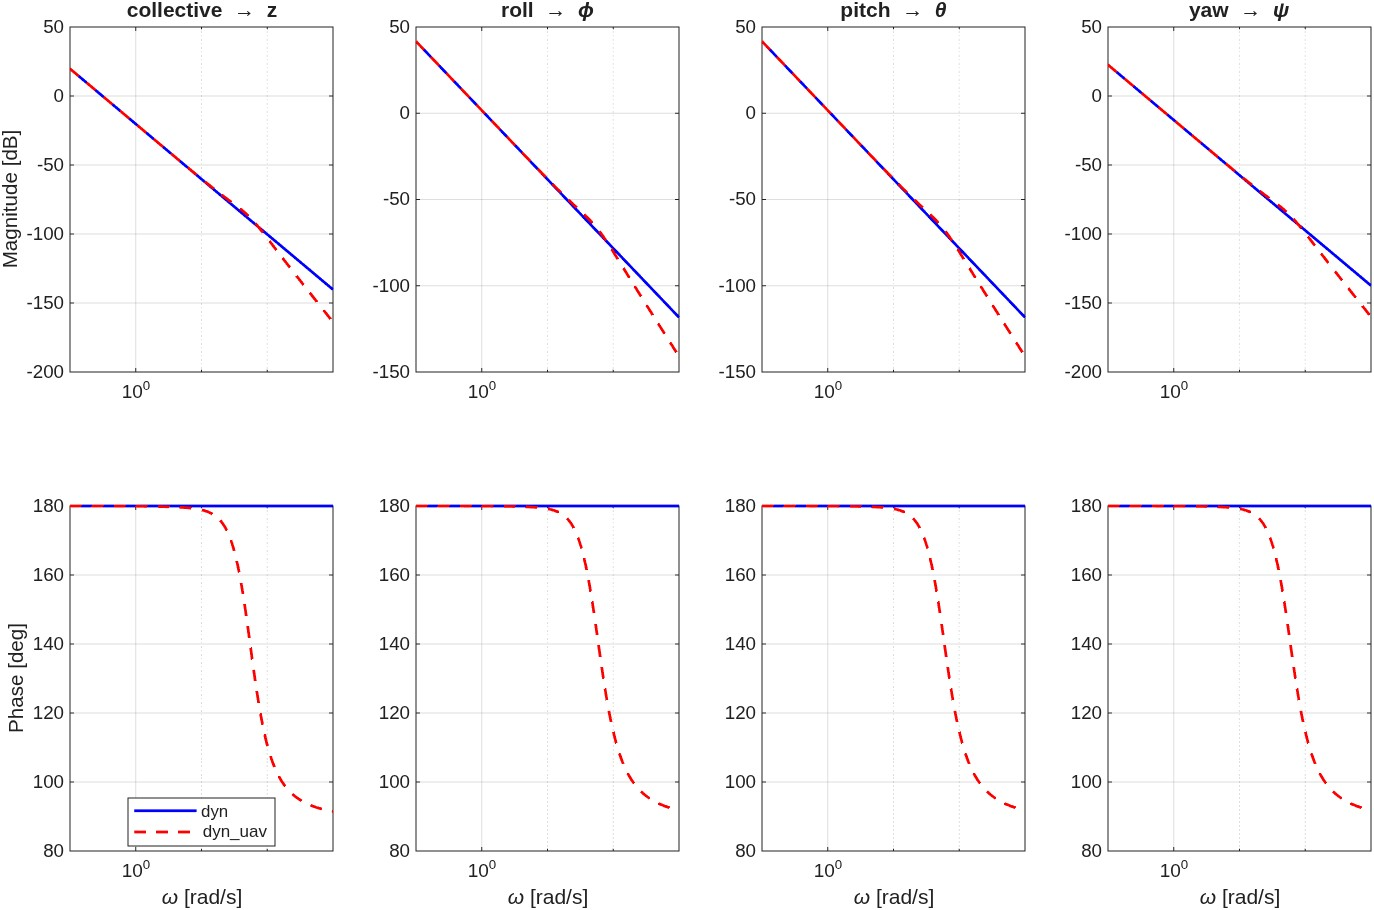 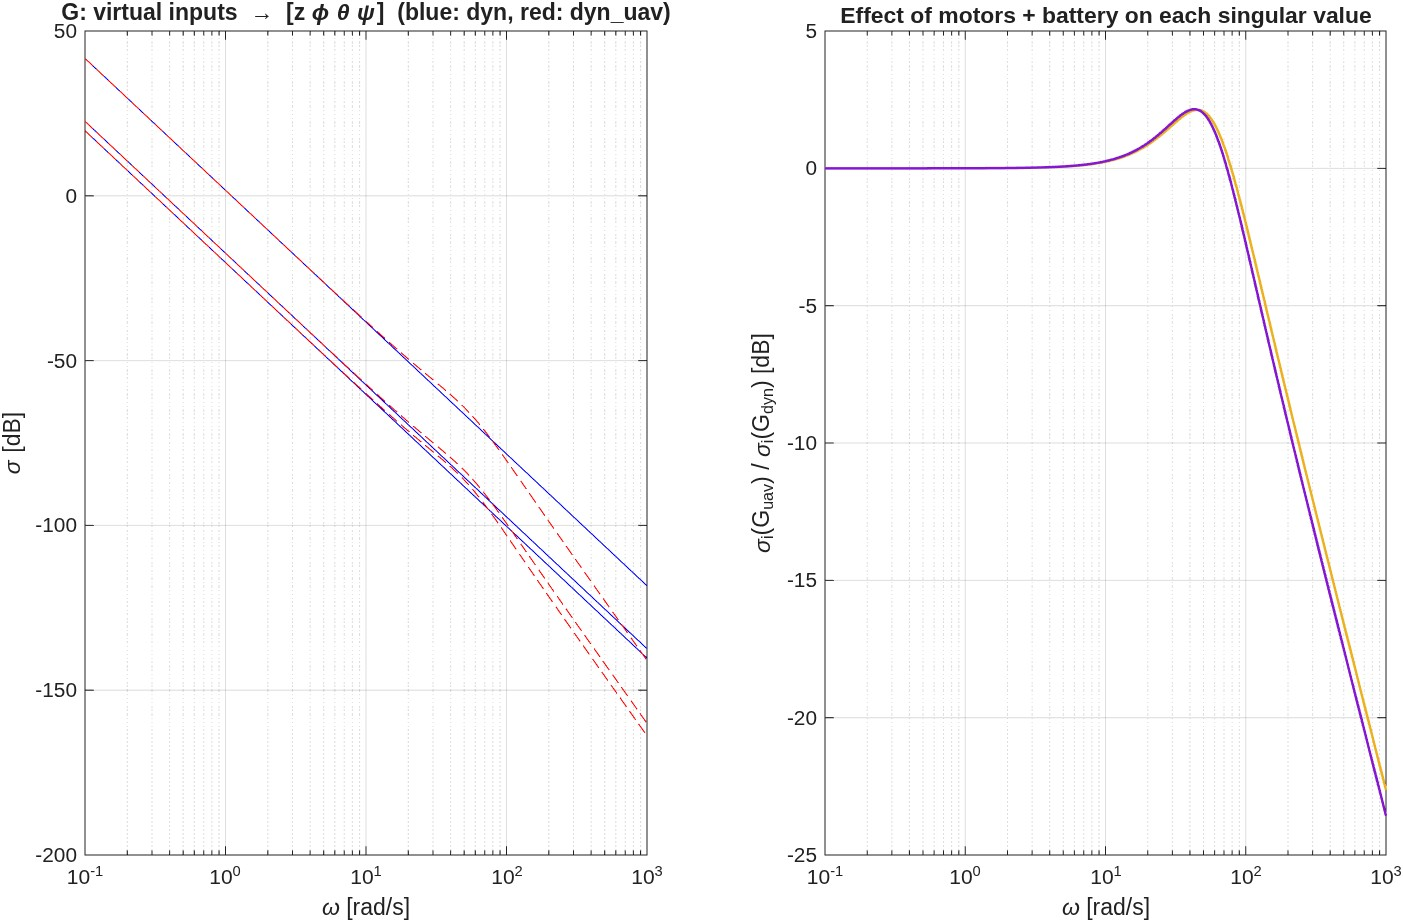

Figures comparing dyn and dyn_uav (`src/compare_models.m`), Bode diagrams on the left and singular values on the right.

 According to `src/test_motor_reduction.m t`he approximation is valid for a simple obstacles-free trajectory: the position error stays at 3.3 cm (roughly 0.05 % of the trajectory) for the motor alone.

function F = dyn_vec(X, U, drone)
% NLP dynamics (16 states): rotor speeds are states, rotor accelerations U are the inputs.
F = [dyn(X(1:12,:), X(13:16,:), drone); U];
end

function d = colloc_defects(X, U, h, drone)
% Trapezoidal collocation defects X_{k+1} - X_k - h/2 (f_k + f_{k+1}), 16 x n.
n = size(X,2) - 1;
F = dyn_vec(X, U, drone);
d = X(:,2:n+1) - X(:,1:n) - h/2*(F(:,1:n) + F(:,2:n+1));
end

prob.Constraints.colloc = (colloc_defects(X, U, h, drone) == 0);   % trapezoidal collocation

**Initial and final nodes constraints**

prob.Constraints.init   = (X(:,1)       == [p0; scen.start_vel(:); zeros(6,1); w_h*ones(4,1)]);
prob.Constraints.pos_f  = (X(1:3,N+1)   == pf);
prob.Constraints.vel_f  = (X(4:6,N+1)   == scen.target_vel(:));
prob.Constraints.att_f  = (X(7:8,N+1)   == 0);
prob.Constraints.rate_f = (X(10:12,N+1) == 0);
prob.Constraints.rot_f  = (X(13:16,N+1) == w_h*ones(4,1));

**Obstacle avoidance using super-ellipsoids**

To model the buildings and prevent the quadrotor from colliding with them, obstacle avoidance constraints are formulated using super-ellipsoids. Each building is represented by a super-ellipsoid centered at ((x_b,y_b,0)), with semi-axes enlarged by a safety margin $(d_{safe})$. The boundary of the obstacle is described by


$$\left(\frac{x-x_b}{a_x+d_{\mathrm{safe}}}\right)^n
+
\left(\frac{y-y_b}{a_y+d_{\mathrm{safe}}}\right)^n
+
\left(\frac{z}{a_z+d_{\mathrm{safe}}}\right)^n
=1,$$


where (a_x), (a_y), and (a_z) are the building's half-width, half-length, and height, respectively. The exponent (n) controls the shape of the super-ellipsoid. In particular, choosing an even exponent greater than two produces a shape closer to a rectangular building while retaining a smooth mathematical representation.

The quadrotor is constrained to remain outside each obstacle. Therefore, at every discretization node (k), the following inequality is imposed:


$$\left(\frac{x_k-x_b}{a_x+d_{\mathrm{safe}}}\right)^n
+
\left(\frac{y_k-y_b}{a_y+d_{\mathrm{safe}}}\right)^n
+
\left(\frac{z_k}{a_z+d_{\mathrm{safe}}}\right)^n
\geq 1.$$


This formulation provides a differentiable obstacle-avoidance constraint that can be handled by the nonlinear programming solver. In the present implementation, an exponent of (n=4) is used. It is worth noting that the constraints are imposed at the discretization nodes; consequently, additional checks along the continuous trajectory are recommended to ensure that no collision occurs between two consecutive nodes.

function s = superellipsoid(P, c, a, p)
% s >= 1 <=> point (columns of P, 3 x M) outside the super-ellipsoid centred at (c(1), c(2), 0)
% with semi-axes a(1:3) and exponent p.
s = ((P(1,:) - c(1))/a(1)).^p + ((P(2,:) - c(2))/a(2)).^p + (P(3,:)/a(3)).^p;
end

for b = 1:scen.n_buildings
    prob.Constraints.(sprintf('obst_%d', b)) = ...
        (superellipsoid(X(1:3,:), bld_c(b,:), bld_a(b,:), p_sq) >= 1);
end

**Initial guess**

smooth step xy (zero speed at the endpoints) + “plateau” altitude profile: rapid ascent, cruising above the tallest building, final descent.

tau   = linspace(0, 1, N+1);
sprof = 3*tau.^2 - 2*tau.^3;
dsdt  = (6*tau - 6*tau.^2) / Tf_init;

z_cruise = max(scen.buildings(:,5)) + 2*scen.ecart;
%z_cruise = max(scen.buildings(:,5));
%z_cruise = 0;
assert(z_cruise < scen.z_max, 'z_cruise = %.1f m must be below z_max = %.1f m', z_cruise, scen.z_max);
sstep  = @(a) 3*min(max(a,0),1).^2 - 2*min(max(a,0),1).^3;
z_prof = z_cruise*(sstep(tau/0.15) - sstep((tau-0.85)/0.15));

X_init = zeros(nx, N+1);
X_init(1:3,:)   = p0 + (pf-p0)*sprof;
X_init(3,:)     = X_init(3,:) + z_prof;
X_init(4:6,:)   = (pf-p0)*dsdt;
X_init(6,:)     = X_init(6,:) + gradient(z_prof, Tf_init/N);
X_init(13:16,:) = w_h;

x0 = struct('Tf', Tf_init, 'X', X_init, 'U', zeros(nu,N+1));

**Problem structure**

solverProb = prob2struct(prob, x0, ...
    'ObjectiveDerivative',   'auto-reverse', ...
    'ConstraintDerivative',  'auto-reverse', ...
    'FileLocation',          'data/generated_fmincon/', ....
    'ObjectiveFunctionName', 'fmincon_objective', ...
    'ConstraintFunctionName','fmincon_constraints');

### Symbolic Hessian of Lagrangian

For a general nonlinear optimization problem,

 $\min_{z} f(z)$, subject to $c_{\mathrm{eq}}(z)=0$ and $c_{\mathrm{ineq}}(z)\leq 0$,

 the Lagrangian is defined as $\mathcal{L}(z,\lambda)
=
f(z)
+
\lambda_{\mathrm{eq}}^{T}c_{\mathrm{eq}}(z)
+
\lambda_{\mathrm{ineq}}^{T}c_{\mathrm{ineq}}(z).$

The Hessian supplied to the solver is therefore $\nabla_{zz}^{2}\mathcal{L}
=
\nabla^{2}f(z)
+
\sum_i \lambda_{\mathrm{eq},i}
\nabla^{2}c_{\mathrm{eq},i}(z)
+
\sum_j \lambda_{\mathrm{ineq},j}
\nabla^{2}c_{\mathrm{ineq},j}(z).$

The multipliers are updated by the optimization algorithm throughout the iterations. Consequently, the Hessian must account not only for the objective function but also for the nonlinear constraints.

Although MATLAB can approximate this matrix numerically or use quasi-Newton approximations, I chose to provide the exact Hessian. This avoids relying on approximations of the second derivatives and can improve the convergence behavior of the interior-point algorithm, particularly for a large nonlinear optimization problem such as this one. The computational cost of evaluating the Hessian is addressed by exploiting the sparse structure of the problem.

The key observation is that the dynamic constraints are formulated using trapezoidal collocation. Each collocation interval only couples the variables at its two neighboring nodes. Therefore, instead of calculating the entire Hessian symbolically, it is sufficient to calculate the Hessian of the Lagrangian associated with one interval.

For interval $k$, the local decision vector is defined as $z_k^{\mathrm{loc}}
=
\left[\matrix{
T_f \cr
x_k \cr
u_k \cr
x_{k+1} \cr
u_{k+1}
}\right]
\in \mathbb{R}^{41},$ where $x_k,x_{k+1}\in\mathbb{R}^{16}$ are the state vectors and $u_k,u_{k+1}\in\mathbb{R}^{4}$ are the control vectors. The corresponding local Lagrangian is $\mathcal{L}_k
=
\frac{E_k}{P_{\mathrm{ref}}}
+
\lambda_k^T d_k$

where $E_k$ is the contribution of interval $k$ to the energy objective, $P_{\mathrm{ref}}$ is a scaling factor, $d_k$ is the vector of collocation defects, and $\lambda_k\in\mathbb{R}^{16}$ contains their associated Lagrange multipliers.

Its exact Hessian is $H_k
=
\nabla_{z_k^{\mathrm{loc}}}^{2}\mathcal{L}_k
\in\mathbb{R}^{41\times41}.$

This local Hessian is generated symbolically using the Symbolic Math Toolbox and exported as a MATLAB function. The symbolic calculation is performed only once, rather than at every optimization iteration. During the optimization, the generated function is evaluated numerically using the current decision variables and Lagrange multipliers.

function gen_hess_loc(drone, mot, N, P_ref)
% Writes hess_loc.m: Hessian (41 x 41) of the Lagrangian of one collocation interval,
% w.r.t. zl = [Tf; x_k; u_k; x_{k+1}; u_{k+1}], for multipliers lam (16 x 1) of its defects.
% (The term c_T*Tf is linear: no contribution.)
syms Tf_s real
xa  = sym('xa',  [16 1], 'real');   ua = sym('ua', [4 1], 'real');
xb  = sym('xb',  [16 1], 'real');   ub = sym('ub', [4 1], 'real');
lam = sym('lam', [16 1], 'real');
zl  = [Tf_s; xa; ua; xb; ub];

X = [xa xb];   U = [ua ub];   h = Tf_s/N;
L = elec_energy(X(13:16,:), U, h, drone, mot)/P_ref + lam.'*colloc_defects(X, U, h, drone);

matlabFunction(hessian(L, zl), 'File','generated_fmincon/hess_loc', 'Vars',{zl, lam}, 'Optimize',true);
rehash;  clear hess_loc
end

gen_hess_loc(drone, mot, N, P_ref);

**Exact Hessian calculations**

The global Hessian is obtained by assembling the local Hessians according to the positions of their corresponding variables in the global decision vector:


$$H_{\mathrm{colloc}}
=
\sum_{k=1}^{N}
S_k^T H_k S_k,$$


`w`here $S_k$ is a Boolean selection matrix mapping the local variables of interval $k$ to their corresponding positions in the global decision vector.

Since two consecutive intervals share their state variables, their local Hessian contributions overlap. These contributions must therefore be added together during assembly.

The global Hessian is highly sparse because each collocation interval only depends on the variables at its two neighboring nodes. Variables belonging to distant intervals do not interact directly, resulting in many structurally zero entries in the Hessian.

Rather than constructing a dense global matrix and subsequently removing its zero entries, the implementation assembles the matrix directly using MATLAB's `sparse` function. The local Hessian entries are mapped to their global row and column indices, and entries corresponding to the same global position are automatically summed. Zero-valued entries are not stored in the resulting sparse matrix.

The obstacle constraints introduce additional contributions to the Hessian. For each building, the inequality constraint is defined as:


$$c_b(r)
=
1-
\left[
\left(\frac{x-x_b}{a_x}\right)^p
+
\left(\frac{y-y_b}{a_y}\right)^p
+
\left(\frac{z}{a_z}\right)^p
\right]
\leq 0.$$


Since this constraint depends only on the position coordinates, its Hessian contributes only to the diagonal entries associated with the corresponding position variables. For an even exponent $p
$, the second derivatives are:


$$\frac{\partial^2 c_b}{\partial x^2}
=
-\frac{p(p-1)(x-x_b)^{p-2}}{a_x^p},$$



$$\frac{\partial^2 c_b}{\partial y^2}
=
-\frac{p(p-1)(y-y_b)^{p-2}}{a_y^p},$$



$$\frac{\partial^2 c_b}{\partial z^2}
=
-\frac{p(p-1)z^{p-2}}{a_z^p}.$$


All mixed second derivatives are zero. Thus, the obstacle contribution is diagonal and can be assembled efficiently without generating another symbolic Hessian.

Finally, the contributions from the collocation constraints and obstacle constraints are combined to obtain the complete Hessian $H
=
H_{\mathrm{colloc}}
+
H_{\mathrm{obstacles}}.$

The remaining constraints, including the boundary conditions,variable bounds, and the linear final-time contribution to the objective, have zero second derivatives and therefore do not

contribute to the Hessian.

This approach provides the exact Hessian of the Lagrangian while exploiting the local structure of the collocation formulation. By assembling only the relevant entries into a sparse matrix, unnecessary storage and computations associated with a dense Hessian are avoided. You can see for yourself in `src/nlp_solv_fmincon_2.m`, the difference in step speed between the exact hessian and `bfgs` or `lbfgs` estimations.

function H = hess_lagr(z, lambda, hs)
% Contributions:
%   1) cost + collocation: sum of the local 41x41 blocks (sparse() adds the overlaps of neighbouring intervals);
%   2) obstacles c_b = 1 - s_b: diagonal, d2c/dr_i^2 = -p(p-1)(r_i - c_i)^(p-2)/a_i^p;
%   3) bounds, boundary conditions, c_T*Tf: linear -> 0.
N  = hs.N;
nl = size(hs.LOC, 1);

% 1) lambda.eqnonlin = defects(:), column-major (16 x N)
lam_eq = reshape(lambda.eqnonlin, [], N);
V = zeros(nl*nl, N);
for k = 1:N
    Hk = hess_loc(z(hs.LOC(:,k)), lam_eq(:,k));
    V(:,k) = Hk(:);
end
H = sparse(hs.I, hs.J, V(:), hs.nz, hs.nz);

% 2) lambda.ineqnonlin = [obst_1 (N+1); obst_2 (N+1); ...]
lam_in = reshape(lambda.ineqnonlin, N+1, hs.nb);
P  = z(hs.IP);                                     % 3 x (N+1) positions
dg = zeros(hs.nz, 1);
for b = 1:hs.nb
    Pc = P - [hs.c(b,:).'; 0];                     % building centre at ground level
    h  = -hs.p*(hs.p-1) * Pc.^(hs.p-2) ./ hs.a(b,:).'.^hs.p;   % 3 x (N+1)
    dg(hs.IP) = dg(hs.IP) + h .* lam_in(:,b).';
end
H = H + spdiags(dg, 0, hs.nz, hs.nz);
end

function Hfun = make_hess_fcn(idx, c, a, p, N)
% Pre-computes the sparse assembly pattern and returns the HessianFcn handle for fmincon.
nx = numel(idx.X)/(N+1);   nu = numel(idx.U)/(N+1);
IX = reshape(idx.X, nx, N+1);
IU = reshape(idx.U, nu, N+1);
LOC = [repmat(idx.Tf,1,N); IX(:,1:N); IU(:,1:N); IX(:,2:N+1); IU(:,2:N+1)];   % 41 x N, rows = zl of hess_loc
nl  = size(LOC,1);

hs.N   = N;
hs.nz  = numel(idx.Tf) + numel(idx.X) + numel(idx.U);
hs.LOC = LOC;
hs.I   = reshape(repmat(reshape(LOC, nl, 1, N), [1 nl 1]), [], 1);   % (row, col) of each local block entry,
hs.J   = reshape(repmat(reshape(LOC, 1, nl, N), [nl 1 1]), [], 1);   % column-major order of Hk(:)
hs.IP  = IX(1:3,:);                                                  % indices of (x,y,z) at each node
hs.c = c;   hs.a = a;   hs.p = p;   hs.nb = size(c,1);

Hfun = @(z, lambda) hess_lagr(z, lambda, hs);
end

idx = varindex(prob); % position of Tf, X, U in the solver vector z
Hfun = make_hess_fcn(idx, bld_c, bld_a, p_sq, N);

### Solving

solverProb.options = optimoptions('fmincon', ...
    'Algorithm',                'interior-point', ...
    'HessianFcn',               Hfun, ...
    'SpecifyObjectiveGradient', true, ...
    'SpecifyConstraintGradient',true, ...
    'ScaleProblem',             true, ...
    'MaxFunctionEvaluations',   1e7, ...
    'MaxIterations',            3000, ...
    'OptimalityTolerance',      1e-5, ...
    'ConstraintTolerance',      1e-5, ...
    'Display',                  'final');

tic
[z_sol, ~, exitflag, output] = fmincon(solverProb);


Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

t_solve = toc;

**Extracting solution**

Tf_sol = z_sol(idx.Tf);
X_sol  = reshape(z_sol(idx.X), nx, N+1);
U_sol  = reshape(z_sol(idx.U), nu, N+1);
t_sol  = linspace(0, Tf_sol, N+1);
E_sol  = elec_energy(X_sol(13:16,:), U_sol, Tf_sol/N, drone, mot);

U_sol contains the accelerations, the angular speeds are found in X_sol(13:16,:).

for b = 1:scen.n_buildings                             % a posteriori check: min s_b must be >= 1
    fprintf('Building %d: min s_b = %.4f (>= 1 required)\n', b, ...
        min(superellipsoid(X_sol(1:3,:), bld_c(b,:), bld_a(b,:), p_sq)));
end

Building 1: min s_b = 1.0000 (>= 1 required)
Building 2: min s_b = 2.8807 (>= 1 required)
Building 3: min s_b = 25.2863 (>= 1 required)
Building 4: min s_b = 1.0000 (>= 1 required)
Building 5: min s_b = 30.2940 (>= 1 required)
Building 6: min s_b = 3.4806 (>= 1 required)


fprintf('Tf = %.2f s | E = %.1f J (hover over Tf: %.1f J)\n', Tf_sol, E_sol, P_ref*Tf_sol);

Tf = 5.81 s | E = 268.2 J (hover over Tf: 166.0 J)


fprintf('exitflag = %d | %d iterations | constraint violation = %.2e | %.1f s (%.3f s/iter)\n', ...
    exitflag, output.iterations, output.constrviolation, t_solve, t_solve/max(output.iterations,1));

exitflag = 1 | 77 iterations | constraint violation = 2.41e-05 | 8.2 s (0.107 s/iter)


## Simulation on the 21-states model

W_ref = X_sol(13:16,:);
SoC0  = 1.0;
x_c   = [X_sol(:,1); SoC0; zeros(4,1)];
odeopts = odeset('RelTol',1e-5, 'AbsTol',1e-7);

t_real = t_sol(1);
x_real = x_c.';
for k = 1:N
    [t_k, x_k] = ode45(@(t,x) dyn_uav(x, W_ref(:,k), drone, batt, mot), t_sol(k:k+1), x_c, odeopts);
    t_real = [t_real; t_k(2:end)];
    x_real = [x_real; x_k(2:end,:)];
    x_c    = x_k(end,:).';
end

x_end = x_real(end,:);

**Terminal errors**

fprintf('Final errors | position: %.4f m | speed: %.4f m/s | attitude: %.4f rad | final SoC: %.5f\n', ...
    norm(x_end(1:3).' - pf), norm(x_end(4:6).' - scen.target_vel(:)), norm(x_end(7:8)), x_end(17));

Final errors | position: 1.8108 m | speed: 0.8232 m/s | attitude: 0.0275 rad | final SoC: 0.94347


### Ideal and real trajectory

**3D View**

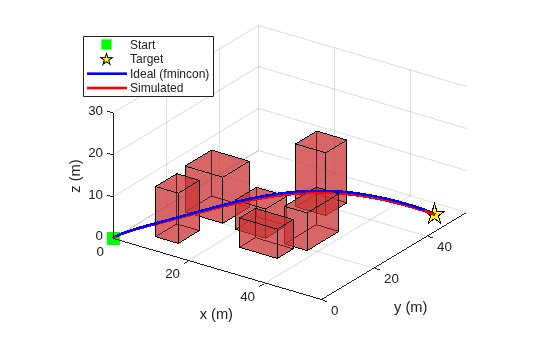

draw_scene(scen);
plot3(X_sol(1,:),  X_sol(2,:),  X_sol(3,:),  'b-', 'LineWidth',2, 'DisplayName','Ideal (fmincon)');
plot3(x_real(:,1), x_real(:,2), x_real(:,3), 'r-', 'LineWidth',2, 'DisplayName','Simulated');
legend('Location','northwest');

**Top view**

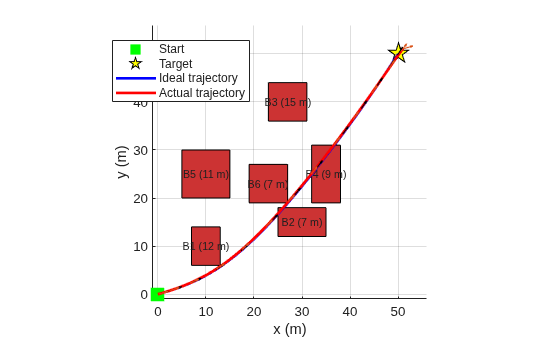

function plot_heading(x, y, vx, vy, color)
% Arrows (length 2 m) along the horizontal velocity, at 15 evenly spread samples.
i = round(linspace(1, numel(x), 15));
v = max(hypot(vx(i), vy(i)), 1e-6);
quiver(x(i), y(i), 2*vx(i)./v, 2*vy(i)./v, 0, 'Color', color, 'HandleVisibility','off');
end

figure; hold on; grid on; axis equal; xlabel('x (m)'); ylabel('y (m)');
xlim([scen.x_min-1 scen.x_max+1]);  ylim([scen.y_min-1 scen.y_max+1]);
for b = 1:scen.n_buildings
    bd = scen.buildings(b,:);
    rectangle('Position', [bd(1)-bd(3), bd(2)-bd(4), 2*bd(3), 2*bd(4)], ...
        'FaceColor',[0.8 0.2 0.2 0.5], 'EdgeColor','k', 'HandleVisibility','off');
    text(bd(1), bd(2), sprintf('B%d (%.0f m)', b, bd(5)), ...
        'HorizontalAlignment','center', 'FontSize',8, 'HandleVisibility','off');
end
plot(p0(1), p0(2), 'gs', 'MarkerSize',12, 'MarkerFaceColor','g', 'DisplayName','Start');
plot(pf(1), pf(2), 'p',  'MarkerSize',16, 'MarkerFaceColor','y', 'MarkerEdgeColor','k', 'DisplayName','Target');
plot(X_sol(1,:),  X_sol(2,:),  'b-', 'LineWidth',2, 'DisplayName','Ideal trajectory');
plot(x_real(:,1), x_real(:,2), 'r-', 'LineWidth',2, 'DisplayName','Actual trajectory');
plot_heading(X_sol(1,:),  X_sol(2,:),  X_sol(4,:),  X_sol(5,:),  'k');
plot_heading(x_real(:,1), x_real(:,2), x_real(:,4), x_real(:,5), [0.85 0.325 0.098]);
legend('Location','best');

**States**

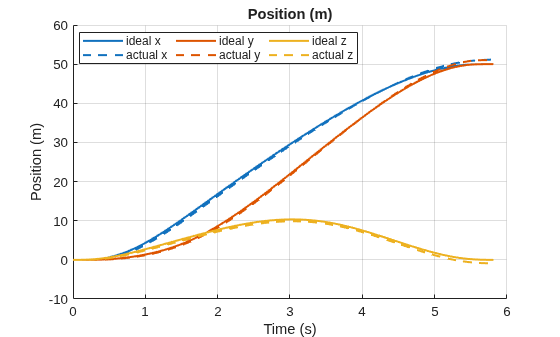

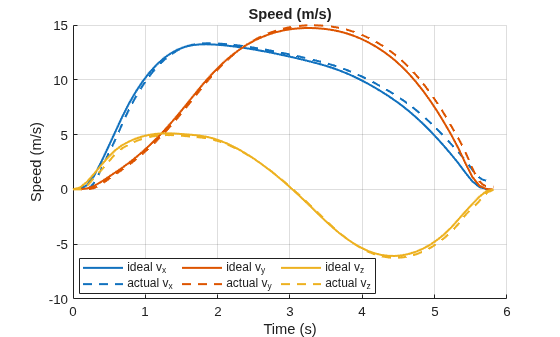

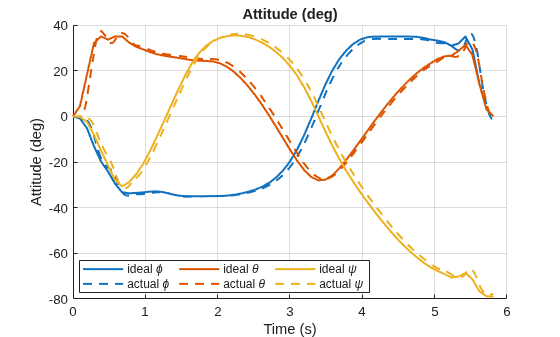

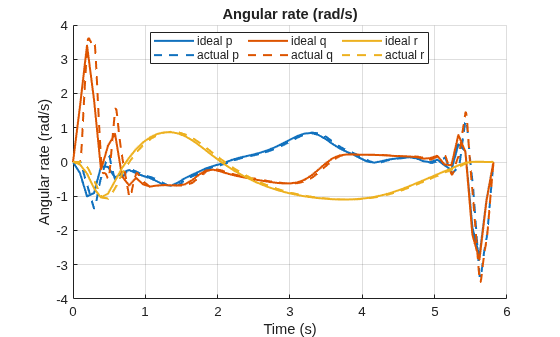

groups = { 1:3,   1,      'Position (m)',         {'x','y','z'};
           4:6,   1,      'Speed (m/s)',          {'v_x','v_y','v_z'};
           7:9,   180/pi, 'Attitude (deg)',       {'\phi','\theta','\psi'};
           10:12, 1,      'Angular rate (rad/s)', {'p','q','r'} };
col = lines(3);
for g = 1:size(groups,1)
    [rows, scale, lbl, names] = groups{g,:};
    figure; hold on; grid on;
    for i = 1:3
        plot(t_sol,  scale*X_sol(rows(i),:),  '-',  'Color',col(i,:), 'LineWidth',1.5, 'DisplayName',['ideal '  names{i}]);
        plot(t_real, scale*x_real(:,rows(i)), '--', 'Color',col(i,:), 'LineWidth',1.5, 'DisplayName',['actual ' names{i}]);
    end
    xlabel('Time (s)'); ylabel(lbl); title(lbl); legend('Location','best','NumColumns',3);
end

**SoC**

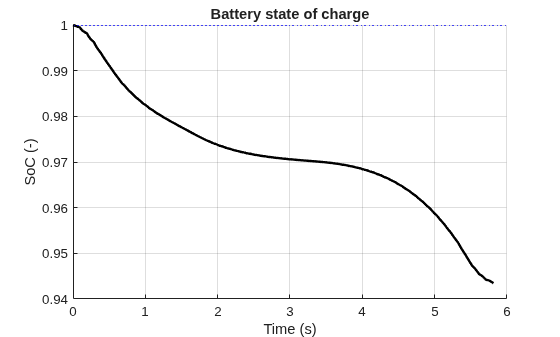

figure; hold on; grid on;
plot(t_real, x_real(:,17), 'k-', 'LineWidth',1.8);
yline(SoC0, 'b:', 'Initial SoC');
xlabel('Time (s)'); ylabel('SoC (-)'); title('Battery state of charge');

**Reference and actual rotor speeds**

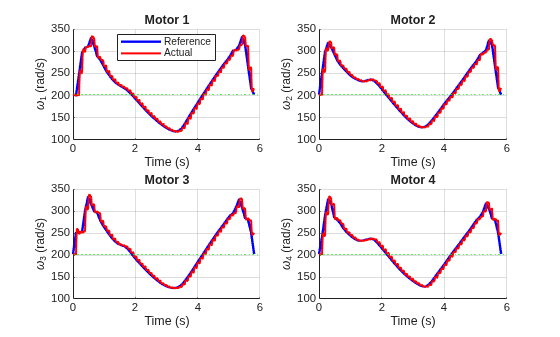

figure;
for i = 1:4
    subplot(2,2,i); hold on; grid on;
    plot(t_sol,  W_ref(i,:),     'b-', 'LineWidth',1.8, 'DisplayName','Reference');
    plot(t_real, x_real(:,12+i), 'r-', 'LineWidth',1.5, 'DisplayName','Actual');
    yline(w_h, 'g:', 'HandleVisibility','off');
    xlabel('Time (s)'); ylabel(sprintf('\\omega_%d (rad/s)', i)); title(sprintf('Motor %d', i));
    if i == 1, legend('Location','best'); end
end

**Optimal commands**

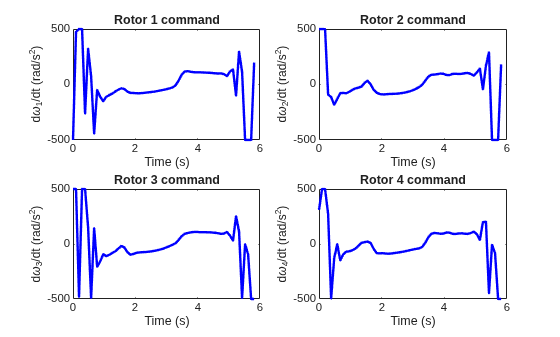

figure;
for i = 1:4
    subplot(2,2,i); grid on;
    plot(t_sol, U_sol(i,:), 'b-', 'LineWidth',1.8);
    xlabel('Time (s)'); ylabel(sprintf('d\\omega_{%d}/dt (rad/s^2)', i)); title(sprintf('Rotor %d command', i));
end

## **Conclusion**

The problem with calculating a trajectory in advance, using an open-loop control system, is that even the slightest disturbance goes undetected by the system and carries through to the end of the sequence.

For a drone flying outdoors, it’s easy to understand this problem.

Using quaternions instead of euler angles could be an improvement, as there would not be a singularity in $\theta = \pm \frac{\pi}{2}$ and we would get rid of Euler's rotation matrix.